## Transducer modelling:

 **Sittig Transfer matrix:**

clear all
x=1;


## variables

w=linspace(2*pi*5*10^5,2*pi*2*10^6,2*10000)   % System angular frequency in rad/s

w = 	1.0e+07 *

    0.3142    0.3142    0.3143    0.3143    0.3143    0.3144    0.3144    0.3145    0.3145    0.3146    0.3146    0.3147    0.3147    0.3148    0.3148    0.3149    0.3149    0.3150    0.3150    0.3151    0.3151    0.3151    0.3152    0.3152    0.3153    0.3153    0.3154    0.3154    0.3155    0.3155    0.3156    0.3156    0.3157    0.3157    0.3158    0.3158    0.3159    0.3159    0.3160    0.3160    0.3160    0.3161    0.3161    0.3162    0.3162    0.3163    0.3163    0.3164    0.3164    0.3165



a=2.5*10^-3;                     % Radius of the piezoelectric plate
rho=7.8*10^3;                    % Piezoelectric plate density
c_33=16.6*10^10;                 % Elastic constant of the plate
d=2*10^-3;                       % plate thickness
Z_b=x*w                         % Acoustic impedance of the backing plate (this is a function of frequency)

Z_b = 	1.0e+07 *

    0.3142    0.3142    0.3143    0.3143    0.3143    0.3144    0.3144    0.3145    0.3145    0.3146    0.3146    0.3147    0.3147    0.3148    0.3148    0.3149    0.3149    0.3150    0.3150    0.3151    0.3151    0.3151    0.3152    0.3152    0.3153    0.3153    0.3154    0.3154    0.3155    0.3155    0.3156    0.3156    0.3157    0.3157    0.3158    0.3158    0.3159    0.3159    0.3160    0.3160    0.3160    0.3161    0.3161    0.3162    0.3162    0.3163    0.3163    0.3164    0.3164    0.3165


d_33=265*10^-12;                 % Piezoelectric charge coefficient
s_33=14.2*10^-12;                % Elastic compliance coefficient
epsilon_0=8.854*10^-12;          % Vacuum permitivity
epsilon_33=1200*epsilon_0;       % relativity Permativity
Beta_33= epsilon_0/epsilon_33;   % the dielectric impermeability of the plate at constant strain,
c=1300;                          % compresisonal wave speed in fluid                     
h_33= d_33/(s_33*epsilon_33);    % Piezoelectric stiffness constant for the plate
v_o=sqrt(c_33/rho);              % compressional wave speed from piezoelectric
k=w/v_o                         % wave number for the peizoelectric plate

k = 	1.0e+03 *

    0.6810    0.6811    0.6812    0.6813    0.6814    0.6815    0.6816    0.6817    0.6818    0.6819    0.6820    0.6821    0.6822    0.6823    0.6824    0.6825    0.6826    0.6827    0.6828    0.6829    0.6830    0.6831    0.6832    0.6833    0.6834    0.6835    0.6836    0.6838    0.6839    0.6840    0.6841    0.6842    0.6843    0.6844    0.6845    0.6846    0.6847    0.6848    0.6849    0.6850    0.6851    0.6852    0.6853    0.6854    0.6855    0.6856    0.6857    0.6858    0.6859    0.6860


S=pi*a^2;                        % Piezoelectric surface area
C_o=S/(Beta_33*d);               % the clamped capacitance of the plate
n=h_33*C_o;                      % A given constant
S_a=S;                           % effective face area of the transducer
rho_2=857;                       % density of the fluid
Kin_Vis=32*10^-6;                % Kinematic Viscosity of the fluid (ISO VG 32)
Vis=Kin_Vis*rho_2;               % Dynamic viscosity of the fluid

Z_o=rho*v_o*S;                   % plane wave acoustic impedance of the piezoelectric plate
c_2=3230;                        %Speed of sound in steel
rho_3=7850;                      %Density of steel
R=((c*rho_2)-(c_2*rho_3))/((c*rho_2)+(c_2*rho_3)); %Reflection coefficient 
L=0.00448;                        %Lentgh of chamber


## Matrix equations




TAe_matrix = zeros(length(w),1);
TAa_matrix = zeros(length(w),1);
TA_matrix = zeros(length(w),1);

for p=1:length(w)
    
    steps1 = 2*p - 1;
    steps2 = 2*p;
    
TAe_matrix(steps1:steps2,1:2) =[1/n n/(1i*w(p)*C_o); -1i*w(p)*C_o 0];         %Transducer electrical matrix
TAa_matrix(steps1:steps2,1:2) =(1/(Z_b(p)-1i*Z_o*tan((k(p))*d/2)))*[Z_b(p)+1i*Z_o*cot(k(p)*d) (Z_o)^2+1i*Z_o*Z_b(p)*cot(k(p)*d); 1 Z_b(p)-2*1i*Z_o*tan(k(p)*d/2)];     %Transducer acoustic matrix

TA_matrix(steps1:steps2,1:2) = TAe_matrix(steps1:steps2,1:2)*TAa_matrix(steps1:steps2,1:2); %Sittig model matrix



end




**Solving for sensitivity **$S_{\textrm{vI}}$**:**

Z_r=S_a*rho_2*c;         % Acoustic radiation impedance

S_vI = zeros(length(w),1);

for kl = 1:length(w)
    
    ste2 = 2*kl;
  S_vI(kl)=1/(Z_r*TA_matrix(ste2,1)+TA_matrix(ste2,2)); %Sensitivity for vI.  
end


**Transducer electrical impedance :**

Z_in = zeros(length(w),1);

for wen = 1:length(w)
ste3 = 2*wen-1;
ste4 = 2*wen;
Z_in(wen) =(Z_r*TA_matrix(ste3,1)+TA_matrix(ste3,2))/(Z_r*TA_matrix(ste4,1)+TA_matrix(ste4,2)); %Electrical impedance of the transducer
end

**Final transfer function **$S_{\textrm{FV}}$**:**

S_FV = zeros(length(w),1)

S_FV =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for phi = 1:length(w)
 S_FV(phi) =Z_r*S_vI(phi)/Z_in(phi); %Sensitivity FV  
end

S_FV_DB=20*log10(abs(S_FV))

S_FV_DB =   -28.1507
  -28.1494
  -28.1481
  -28.1468
  -28.1455
  -28.1442
  -28.1429
  -28.1416
  -28.1403
  -28.1390


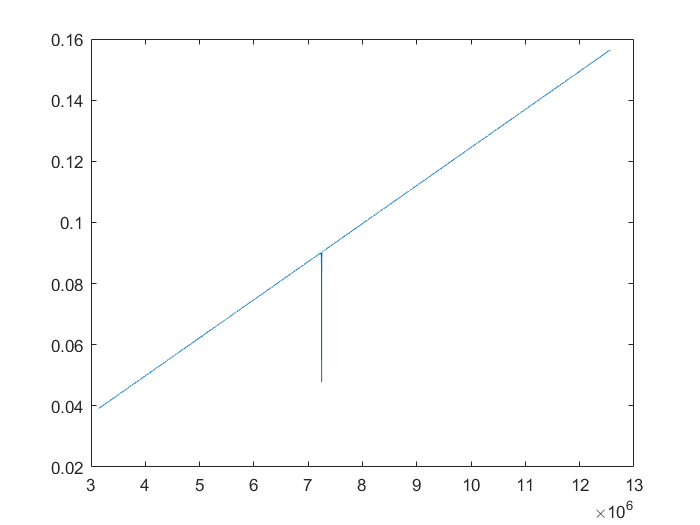

plot(w,abs(S_FV))

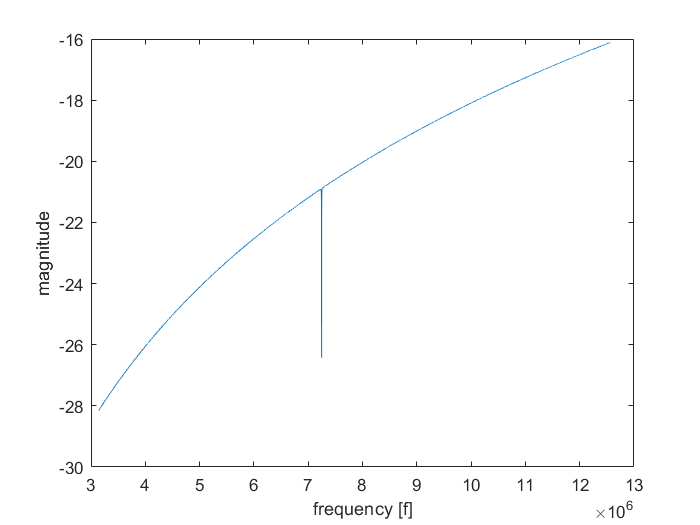

plot(w,S_FV_DB)
xlabel('frequency [f]')
ylabel(['magnitude'])

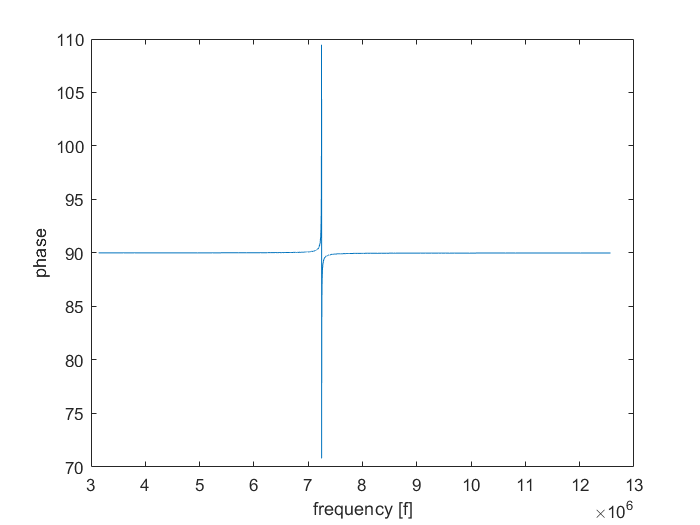

plot(w,rad2deg(angle(S_FV)))

xlabel('frequency [f]')
ylabel('phase')